# Lab11: 

Team1: Dmitry Shadrin, Eugenii Israelit, Sergey Golovanov @Skoltech

Part I. 

clc; clear; close all;
addpath('functions/');

n = 500;

x1 = 1000;
vx1 = 10;
y1 = 1000;
vy1 =10;
t = 1; 

sigmaA = 0.3;
AccX = normrnd(0, sigmaA, 1, n );
AccY = normrnd(0, sigmaA, 1, n );
X = calcTrajectory11( AccX, x1, vx1, t);
Y = calcTrajectory11( AccY, y1, vy1, t);


sigmaB = 0.004;
sigmaD = 50;
BNoise = normrnd(0,sigmaB,1,n);
DNoise = normrnd(0,sigmaD,1,n);

D = sqrt( X.^2 + Y.^2 );  
B = atan( X ./ Y );
Dm = D + DNoise;
Bm = B + BNoise;
Z = [Dm; Bm];

% figure ('position', [0, 0, 800, 300]); hold on;
% subplot(1,2,1);
% polar(B,D);hold on;
% polar(Bm,Dm);
% axis([0 inf 0 inf]);
% view([90 -90]);
% 
% subplot(1,2,2);
% plot(X,Y); hold on
% axis([0 10000 0 10000])


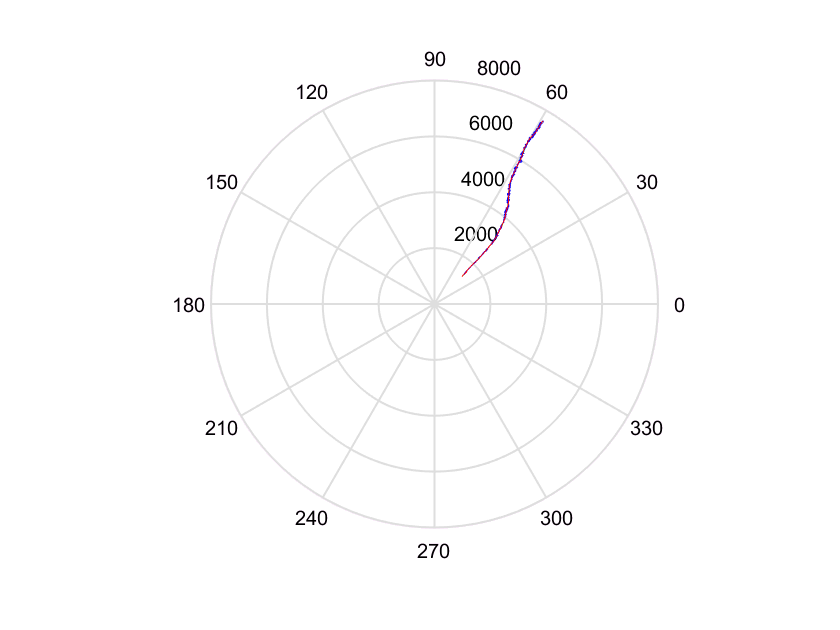

P = [ 10^10 0 0 0; 0 10^10 0 0; 0 0 10^10 0; 0 0 0 10^10 ];
F = [ 1 t 0 0; 0 1 0 0; 0 0 1 t; 0 0 0 1 ]; 
G = [ (t^2)/2 0; t 0; 0 (t^2)/2; 0 t ];

Q = G * G' * sigmaA^2;
R = [ sigmaD^2 0; 0 sigmaB^2 ];

Z0 = [ Dm(1)*sin(Bm(1)); 0 ; Dm(1)*cos(Bm(1)); 0 ];
Xk = calcKalmanExtended(Z, Z0, F, P, Q, R );
 
Dk = sqrt( Xk(1,:).^2 + Xk(3,:).^2 );  
Bk = atan( Xk(1,:) ./ Xk(3,:) );


% figure ('position', [0, 0, 800, 300]); hold on;
% subplot(1,2,1);
polar(B,D,'green');hold on;
polar(Bm,Dm, 'blue');
polar(Bk,Dk, 'red');

Axis([0 inf 0 inf]);

Cannot find an exact (case-sensitive) match for 'Axis'

The closest match is: axis in C:\dev\MATLAB\R2016a\toolbox\matlab\graph2d\axis.p



% view([90 -90]);

% subplot(1,2,2);
% plot(X,Y); hold on
% plot(Xk(1,:),Xk(3,:)) 
% axis([0 10000 0 10000])